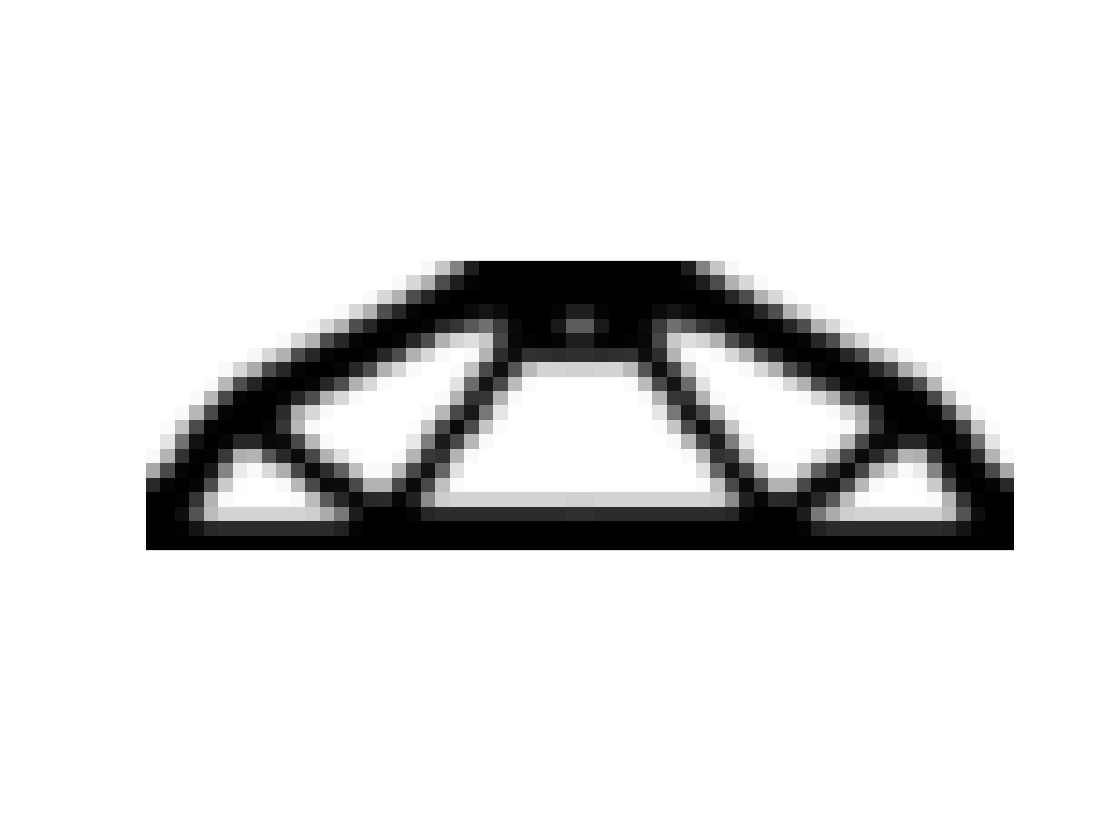

 It.:    1 Obj.:   306.1067 Vol.:  0.450 ch.:  0.200
 It.:    2 Obj.:   180.8413 Vol.:  0.450 ch.:  0.200
 It.:    3 Obj.:   130.7928 Vol.:  0.450 ch.:  0.200
 It.:    4 Obj.:   104.2729 Vol.:  0.450 ch.:  0.200
 It.:    5 Obj.:    92.5193 Vol.:  0.450 ch.:  0.200
 It.:    6 Obj.:    83.9739 Vol.:  0.450 ch.:  0.200
 It.:    7 Obj.:    78.0387 Vol.:  0.450 ch.:  0.198
 It.:    8 Obj.:    74.0206 Vol.:  0.450 ch.:  0.177
 It.:    9 Obj.:    71.5069 Vol.:  0.450 ch.:  0.198
 It.:   10 Obj.:    69.5731 Vol.:  0.450 ch.:  0.187
 It.:   11 Obj.:    67.9262 Vol.:  0.450 ch.:  0.189
 It.:   12 Obj.:    66.3690 Vol.:  0.450 ch.:  0.164
 It.:   13 Obj.:    64.9109 Vol.:  0.450 ch.:  0.169
 It.:   14 Obj.:    63.5759 Vol.:  0.450 ch.:  0.158
 It.:   15 Obj.:    62.5145 Vol.:  0.450 ch.:  0.188
 It.:   16 Obj.:    61.6717 Vol.:  0.450 ch.:  0.160
 It.:   17 Obj.:    60.9643 Vol.:  0.450 ch.:  0.190
 It.:   18 Obj.:    60.3440 Vol.:  0.450 ch.:  0.181
 It.:   19 Obj.:    59.8176 Vol.:  0.450 ch.: 

ans = 55.9292

clear all; close all;

%60x30 default
 fact = 1;
 nelx= 30*fact;
 nely= 20*fact;
 nele = nelx*nely;
 volfrac = 0.45;
 penal = 3;
 rmin = 1.5;
 MOVE_LIMIT = 0.8;
 epsilon = 1e-5;
 ft = 2;
 
figure;
top88(nelx,nely,volfrac,penal,rmin,ft)

figure;
%thanks to 
top88_plusAM_qp_primal(nelx,nely,volfrac,penal,rmin,ft)

 It.:    1 Obj.:    61.9866 Vol.:  0.450 ch.:  0.028
 It.:    2 Obj.:    57.0339 Vol.:  0.450 ch.:  0.039
 It.:    3 Obj.:    49.0790 Vol.:  0.450 ch.:  0.071
 It.:    4 Obj.:    44.8025 Vol.:  0.450 ch.:  0.083
 It.:    5 Obj.:    43.3374 Vol.:  0.450 ch.:  0.089
 It.:    6 Obj.:    42.7007 Vol.:  0.450 ch.:  0.085
 It.:    7 Obj.:    42.4104 Vol.:  0.450 ch.:  0.084
 It.:    8 Obj.:    42.2515 Vol.:  0.450 ch.:  0.083
 It.:    9 Obj.:    42.1539 Vol.:  0.450 ch.:  0.082
 It.:   10 Obj.:    42.0897 Vol.:  0.450 ch.:  0.082
 It.:   11 Obj.:    42.0451 Vol.:  0.450 ch.:  0.082
 It.:   12 Obj.:    42.0129 Vol.:  0.450 ch.:  0.082
 It.:   13 Obj.:    41.9889 Vol.:  0.450 ch.:  0.082
 It.:   14 Obj.:    41.9705 Vol.:  0.450 ch.:  0.082
 It.:   15 Obj.:    41.9561 Vol.:  0.450 ch.:  0.082
 It.:   16 Obj.:    41.9447 Vol.:  0.450 ch.:  0.082
 It.:   17 Obj.:    41.9356 Vol.:  0.450 ch.:  0.081
 It.:   18 Obj.:    41.9281 Vol.:  0.450 ch.:  0.081
 It.:   19 Obj.:    41.9214 Vol.:  0.450 ch.: 

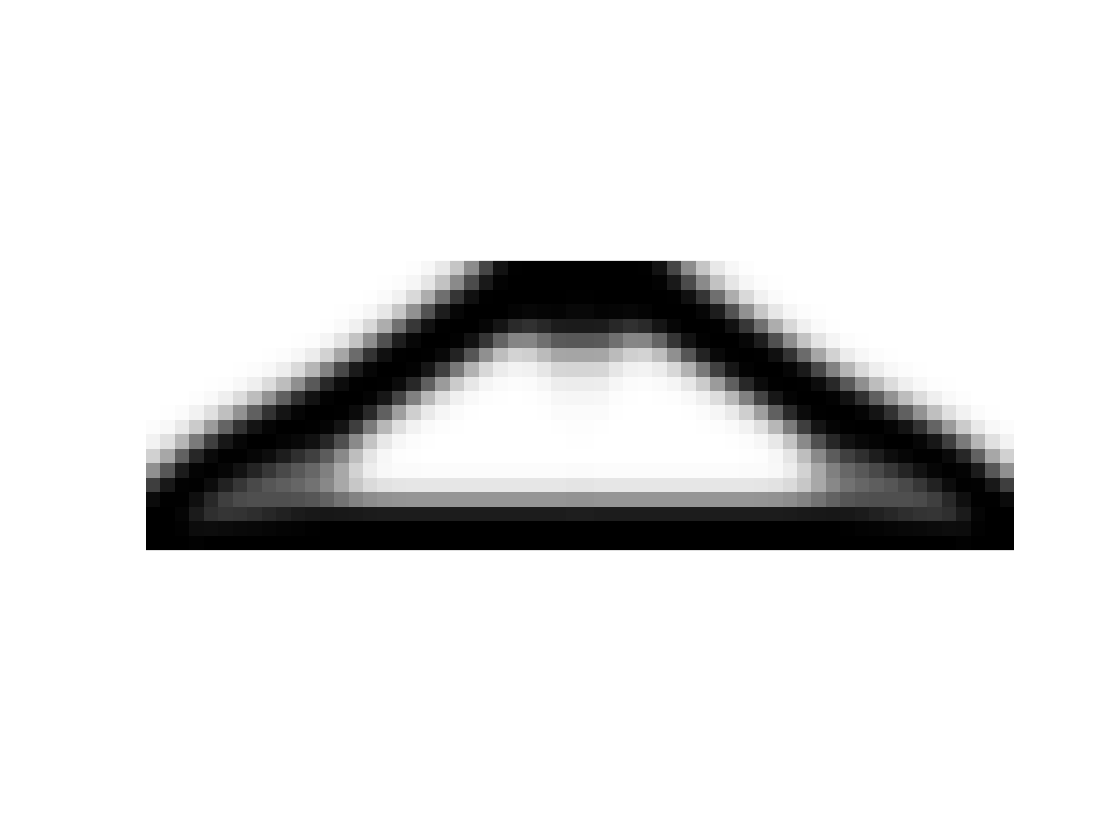

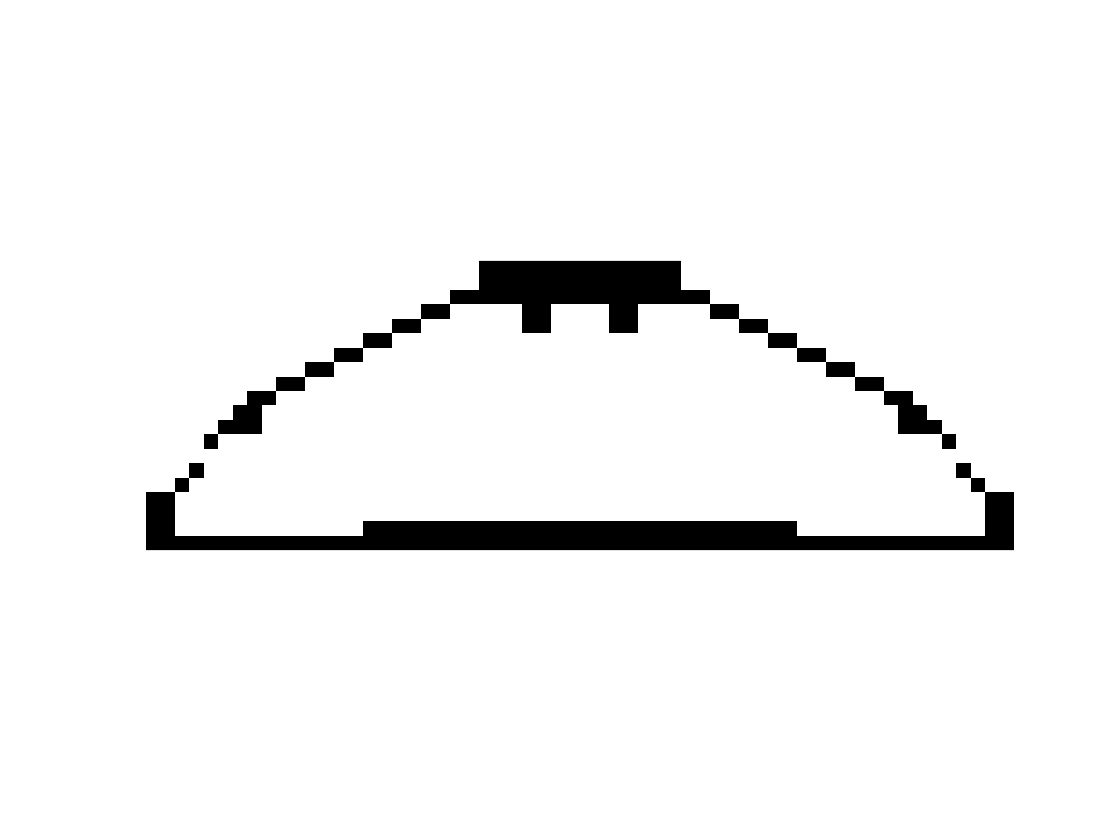



load A
load ref
%display common part
colormap(gray); imagesc(A&ref); caxis([0 1]); axis equal; axis off; drawnow;


% %Comparison
% load A
% load ref
% %[1] Zhou, W., A. C. Bovik, H. R. Sheikh, and E. P. Simoncelli. "Image Quality Assessment: From Error Visibility to Structural Similarity." IEEE Transactions on Image Processing. Vol. 13, Issue 4, April 2004, pp. 600–612.
% %Calculate the global SSIM value for the image and local SSIM values for each pixel.
% [ssimval,ssimmap] = ssim(A,ref);
% figure;
% %Display the local SSIM map. Include the global SSIM value in the figure title. Small values of local SSIM appear as dark pixels in the local SSIM map. Regions with small local SSIM value correspond to areas where the blurred image noticeably differs from the reference image. Large values of local SSIM value appear as bright pixels. Regions with large local SSIM correspond to uniform regions of the reference image, where blurring has less of an impact on the image.
% imshow(ssimmap,[])
% title("Local SSIM Map with Global SSIM Value: "+num2str(ssimval))